# Testar Runge-Kutta de Ordem 4

26/04/2021     Paulo Gouveia        a2020121705.isec.pt

26/04/2021     Miguel Ferreira       a2020107016.isec.pt

26/04/2021     Pablo Amaral         a2020143935.isec.pt

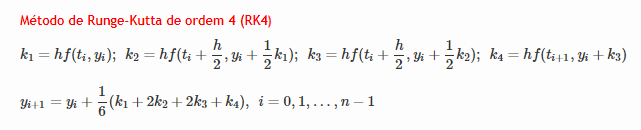

clear
%help function_handle

syms y(t)

f =@(t,y) y+exp(3*t)

f = function_handle with value:
    @(t,y)y+exp(3*t)


%f(0,1)
a = 1

a = 1

b = 2

b = 2

n = 20

n = 20

y0 = 2

y0 = 2



yRK4 = NRK4(f,a,b,n,y0)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


yRK4 =     2.0000    3.2129    4.6677    6.4058    8.4757   10.9334   13.8446   17.2855   21.3448   26.1257   31.7483   38.3523   46.1003   55.1812   65.8148   78.2566   92.8037  109.8015  129.6517  152.8209  179.8519



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

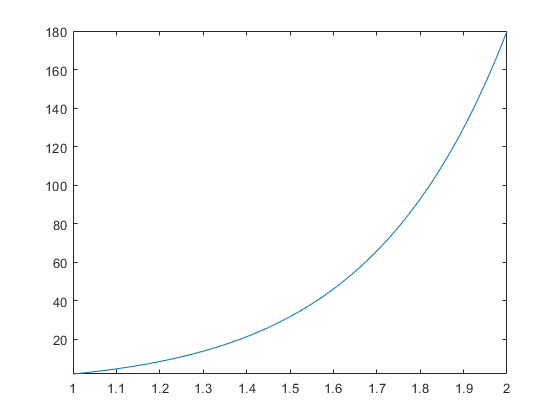

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroRK4 = abs(yExata-yRK4);
tabela = [t.',yExata.',yRK4.',erroRK4.']

tabela =     1.0000    2.0000    2.0000    0.0000
    1.0500    3.2129    3.2129    0.0000
    1.1000    4.6677    4.6677    0.0000
    1.1500    6.4058    6.4058    0.0000
    1.2000    8.4757    8.4757    0.0000
    1.2500   10.9334   10.9334    0.0000
    1.3000   13.8446   13.8446    0.0000
    1.3500   17.2855   17.2855    0.0000
    1.4000   21.3448   21.3448    0.0000
    1.4500   26.1257   26.1257    0.0000


array2table(tabela,"VariableNames",{'t','Exata','RK4','erroRK4'})

ans = 21×4 table
     t      Exata      RK4       erroRK4  
    ____    ______    ______    __________

       1         2         2    1.7764e-15
    1.05    3.2129    3.2129    1.5834e-07
     1.1    4.6677    4.6677    3.5275e-07
    1.15    6.4058    6.4058    5.8973e-07
     1.2    8.4757    8.4757    8.7688e-07
    1.25    10.933    10.933     1.223e-06
     1.3    13.845    13.845    1.6385e-06
    1.35    17.285    17.285    2.1354e-06
     1.4    21.345    21.345    2.7278e-06
    1.45    26.126    26.126    3.4319e-06
     1.5    31.748    31.748     4.267e-06
    1.55    38.352    38.352    5.2552e-06
     1.6      46.1      46.1    6.4225e-06
    1.65    55.181    55.181    7.7989e-06
     1.7    65.815    65.815    9.4197e-06
    1.75    78.257    78.257    1.1326e-05


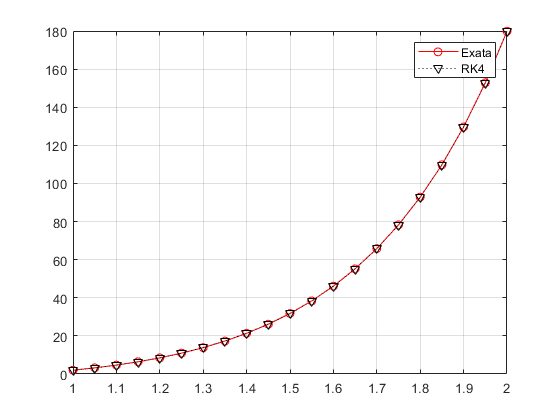


plot(t,yExata,"-ro")
hold on
plot(t,yRK4,"kv:")
hold off
grid on
legend('Exata','RK4')


%whos

 
